% we will create 4 guassian clusters and then attempt 
% to discover them with k = 4 kmeans clustering

% we begin by selecting for mu's and sigma's
% here were are getting some helpf from - https://www.mathworks.com/help/stats/gmdistribution.cluster.html
mu1 = [4 4];          % Mean of the 1st component
sigma1 = [2 0; 0 1];  % Covariance of the 1st component
mu2 = [4 -2];        % Mean of the 2nd component
sigma2 = [1 0; 0 1];  % Covariance of the 2nd component
mu3 = [-4 6];          % Mean of the 3rd component
sigma3 = [3 0; 0 2];  % Covariance of the 3rd component
mu4 = [-4 -2];        % Mean of the 4th component
sigma4 = [1 0; 0 1];  % Covariance of the 4th component

rng('default') % For reproducibility

% generate 250 - 325 points in each cluster
r1 = mvnrnd(mu1,sigma1,250);
r2 = mvnrnd(mu2,sigma2,275);
r3 = mvnrnd(mu3,sigma3,300);
r4 = mvnrnd(mu4,sigma4,325);
X = [r1; r2; r3; r4];

% set some colors for using later
colors = [[0 0.4470 0.7410]; [0.8500 0.3250 0.0980]; [0.9290 0.6940 0.1250]; [0.4940 0.1840 0.5560]; [0.4660 0.6740 0.1880]; [0.3010 0.7450 0.9330]; [0.6350 0.0780 0.1840]];

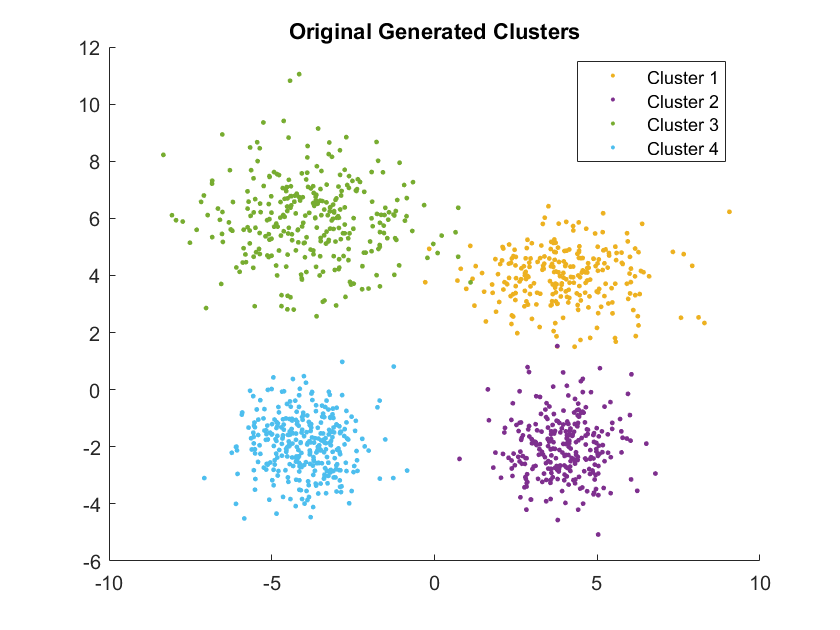

% lets look at the initial clusters

figure;
scatter(r1(:,1),r1(:,2),50,colors(3,:),'.'); % Scatter plot with points of size 10
hold on;
scatter(r2(:,1),r2(:,2),50,colors(4,:),'.'); % Scatter plot with points of size 10
hold on;
scatter(r3(:,1),r3(:,2),50,colors(5,:),'.'); % Scatter plot with points of size 10
hold on;
scatter(r4(:,1),r4(:,2),50,colors(6,:),'.'); % Scatter plot with points of size 10
title('Original Generated Clusters');
legend('Cluster 1','Cluster 2','Cluster 3','Cluster 4','Location','best');

% we now choose k centroids randomly to begin the k means opperation
k = 4;

rng('default'); % For reproducibility

initial = randperm(size(X,1),k);
k_centroids = X(initial,:);

% create empty distance and membership vectors
distances = zeros(size(X,1), k);
previous_membership = zeros(size(X,1),1)

previous_membership =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


% run alternating procedure until points are no longer being reassigned
while true
    % find the distances from each point to each centroid    
    for idx = 1:k
        distances(:,idx) = vecnorm(X-k_centroids(idx,:), 2, 2);
    end
    
    % assign all points to their nearest centroid
    [~, membership] = min(distances, [], 2);
    if membership == previous_membership
       break;
    end
    previous_membership = membership;
    % compute the centroid for the new cluster
    for centroid = 1:k
        idx_k = membership(:,1) == centroid;
        k_centroids(centroid,:) = mean(X(idx_k,:), 1);
    end    
end

sse = 0

sse = 0

for centroid = 1:k
    idx_k = previous_membership(:,1) == centroid;
    sse = sse + sum(distances(idx_k,centroid).^2,"all");
end

% plot clusters
starting_centroids = X(initial,:)

starting_centroids =    -4.2494   -3.1542
   -3.7359   -2.6590
    2.6152    3.7901
   -4.5278   -2.0204


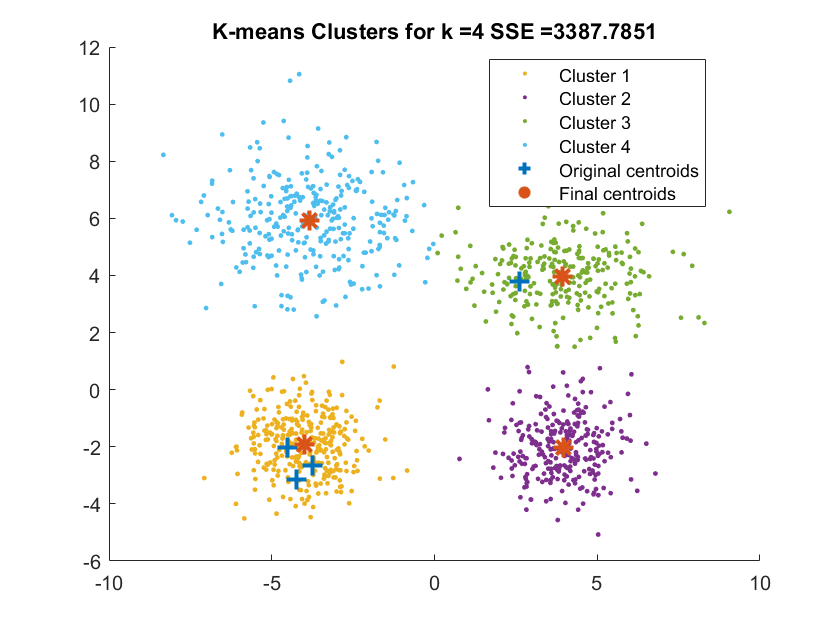

figure;
for cluster = 1:k
    idx_k = previous_membership(:,1) == cluster;
    scatter(X(idx_k, 1),X(idx_k,2),50, colors(cluster+2,:),'.'); % Scatter plot with points of size 10
    hold on; 
end
scatter(starting_centroids(:, 1),starting_centroids(:,2),100,colors(1,:),'+','LineWidth',2); % Scatter plot with points of size 20
hold on;
scatter(k_centroids(:, 1),k_centroids(:,2),100,colors(2,:),'*','LineWidth',2); % Scatter plot with points of size 20
title(strcat('K-means Clusters for k = ', string(k), ' SSE = ', string(sse)));
legend('Cluster 1','Cluster 2','Cluster 3','Cluster 4','Original centroids', 'Final centroids','Location','best');

% spectral relaxation k-means
k = 4;

rng('default'); % For reproducibility

% get the eigenvectors of the similarity matrix
% [V,D] = eig(X*X');
% [~,idx] = sort(abs(diag(D)), 'descend');
[~,~,V] = svd(X*X');

% select top k eigenvectors
% Y = V(:,idx(1:k));
Y = V(:,1:k);
disp(size(Y))

        1150           4





% initial = randperm(size(Y,1),k);
k_centroids = Y(initial,:);


% create empty distance and membership vectors
distances = zeros(size(Y,1), k);
previous_membership = zeros(size(Y,1),1);

% run alternating procedure until points are no longer being reassigned
while true
    % find the distances from each point to each centroid    
    for idx = 1:k
        distances(:,idx) = vecnorm(Y-k_centroids(idx,:), 2, 2);
    end
    
    % assign all points to their nearest centroid
    [~, membership] = min(distances, [], 2);
    if membership == previous_membership
       break;
    end
    previous_membership = membership;
    % compute the centroid for the new cluster
    for centroid = 1:k
        idx_k = membership(:,1) == centroid;
        k_centroids(centroid,:) = mean(Y(idx_k,:), 1);
    end    
end


% plot clusters
starting_centroids = X(initial,:)

starting_centroids =    -4.2494   -3.1542
   -3.7359   -2.6590
    2.6152    3.7901
   -4.5278   -2.0204


% compute the final centroids and distances in the original dimensions
k_centroids = zeros(k,2)

k_centroids =      0     0
     0     0
     0     0
     0     0


distances = zeros(size(X,1), k);
for centroid = 1:k
    idx_k = previous_membership(:,1) == centroid;
    k_centroids(centroid,:) = mean(X(idx_k,:), 1);
    distances(:,centroid) = vecnorm(X-k_centroids(centroid,:), 2, 2);
end

sse = 0

sse = 0

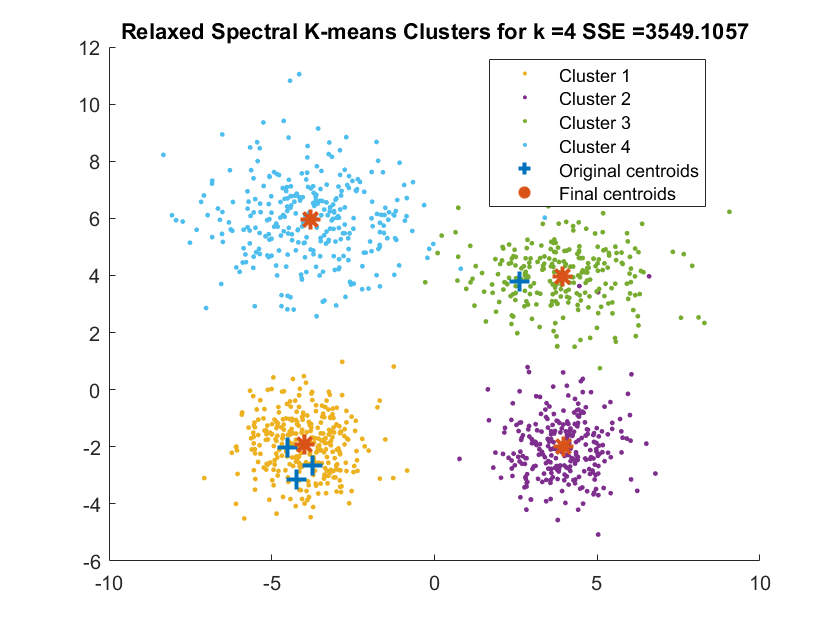

for centroid = 1:k
    idx_k = previous_membership(:,1) == centroid;
    sse = sse + sum(distances(idx_k,centroid).^2,"all");
end

figure;    
for cluster = 1:k
    idx_k = previous_membership(:,1) == cluster;
    scatter(X(idx_k, 1),X(idx_k,2),50, colors(cluster+2,:),'.'); % Scatter plot with points of size 10
    hold on; 
end
scatter(starting_centroids(:, 1),starting_centroids(:,2),100,colors(1,:),'+','LineWidth',2); % Scatter plot with points of size 20
hold on;
scatter(k_centroids(:, 1),k_centroids(:,2),100,colors(2,:),'*','LineWidth',2); % Scatter plot with points of size 20
title(strcat('Relaxed Spectral K-means Clusters for k = ', string(k), ' SSE = ', string(sse)));
legend('Cluster 1','Cluster 2','Cluster 3','Cluster 4','Original centroids', 'Final centroids','Location','best');